# Pronóstico de Precios del Petróleo Crudo Utilizando Descomposición Wavelet Basada en Eliminación de Ruido con Modelo ARMA

% Cargar datos desde un archivo CSV
data = readtable('MCEI.csv');

prices = str2double(data.Price); % Suponiendo que la columna de precios se llama 'Prices'
dates = datetime(data.Date, 'InputFormat', 'dd-MM-yyyy'); % Suponiendo que la columna de fechas se llama 'Date'

% Filtrar el intervalo de tiempo deseado
start_date = datetime('01-Jan-2019', 'InputFormat', 'dd-MMM-yyyy');
end_date = datetime('30-Jul-2021', 'InputFormat', 'dd-MMM-yyyy');
date_filter = (dates >= start_date) & (dates <= end_date);

% Aplicar filtro a precios y fechas
filtered_prices = prices(date_filter);
filtered_dates = dates(date_filter);

#### Transformacion logaritmica

% Transformación logarítmica
log_returns = log(filtered_prices(2:end) ./ filtered_prices(1:end-1));

#### Descomposicion Wavelet

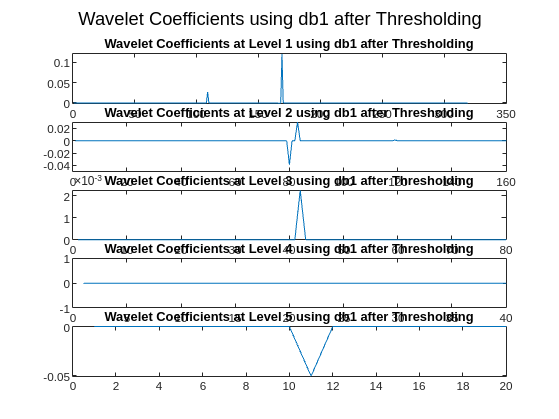

% Descomposición Wavelet y Desnoising
wavelet_families = {'db1', 'db2', 'db3', 'db4', 'db5', 'db6', 'db7', 'db8', 'db9', 'db10', 'sym10'};

% Prealocar espacio para resultados
denoised_data = cell(length(wavelet_families), 1);
noisy_data = cell(length(wavelet_families), 1);

for i = 1:length(wavelet_families)
    wname = wavelet_families{i};
    
    % Descomposición wavelet
    [C, L] = wavedec(log_returns, 5, wname);
    
    % Umbral universal usando el método Donoho-Johnstone
    sigma = median(abs(C)) / 0.6745;
    threshold = sigma * sqrt(2 * log(length(log_returns)));
    
    % Aplicar umbralización
    C_thresh = wthresh(C, 's', threshold);
    
    % Reconstrucción de la señal denoised
    denoised_data{i} = waverec(C_thresh, L, wname);
    noisy_data{i} = log_returns - denoised_data{i};
    
    % Visualización de coeficientes wavelet por nivel después de umbralización
    figure;
    for level = 1:length(L)-2
        coeffs = detcoef(C_thresh, L, level);
        subplot(length(L)-2, 1, level);
        plot(coeffs);
        title(sprintf('Wavelet Coefficients at Level %d using %s after Thresholding', level, wname));
    end
    sgtitle(sprintf('Wavelet Coefficients using %s after Thresholding', wname));
    pause; % Pausa para visualizar cada wavelet
end

#### Modelos de Predicción


% Configuración del modelo ARMA
max_p = 4; % Máximo orden AR
max_q = 4; % Máximo orden MA

% Prealocar espacio para resultados de predicción
results = struct();

for i = 1:length(wavelet_families)
    % Datos denoised y noisy
    denoised = denoised_data{i};
    noisy = noisy_data{i};
    
    % Modelos ARMA para datos denoised
    for p = 0:max_p
        for q = 0:max_q
            if p > 0 || q > 0
                model = arima(p, 0, q);
                [fit, ~, logL] = estimate(model, denoised, 'Display', 'off');
                
                % Guardar resultados
                results(i).wavelet = wavelet_families(i);
                results(i).denoised(p+1, q+1).model = fit;
                results(i).denoised(p+1, q+1).logL = logL;
                
                % RMSE y MAD
                residuals = infer(fit, denoised);
                results(i).denoised(p+1, q+1).rmse = sqrt(mean(residuals.^2));
                results(i).denoised(p+1, q+1).mad = mean(abs(residuals));
            end
        end
    end
    
    % Modelos ARMA para datos noisy
    for p = 0:max_p
        for q = 0:max_q
            if p > 0 || q > 0
                model = arima(p, 0, q);
                [fit, ~, logL] = estimate(model, noisy, 'Display', 'off');
                
                % Guardar resultados
                results(i).noisy(p+1, q+1).model = fit;
                results(i).noisy(p+1, q+1).logL = logL;
                
                % RMSE y MAD
                residuals = infer(fit, noisy);
                results(i).noisy(p+1, q+1).rmse = sqrt(mean(residuals.^2));
                results(i).noisy(p+1, q+1).mad = mean(abs(residuals));
            end
        end
    end
end

% Evaluación de Resultados
% Mostrar resultados
for i = 1:length(wavelet_families)
    fprintf('Wavelet: %s\n', wavelet_families(i));
    fprintf('Denoised Data:\n');
    for p = 1:max_p+1
        for q = 1:max_q+1
            if isfield(results(i).denoised(p, q), 'model')
                fprintf('ARMA(%d,%d): RMSE=%.4f, MAD=%.4f\n', p-1, q-1, results(i).denoised(p, q).rmse, results(i).denoised(p, q).mad);
            end
        end
    end
    fprintf('Noisy Data:\n');
    for p = 1:max_p+1
        for q = 1:max_q+1
            if isfield(results(i).noisy(p, q), 'model')
                fprintf('ARMA(%d,%d): RMSE=%.4f, MAD=%.4f\n', p-1, q-1, results(i).noisy(p, q).rmse, results(i).noisy(p, q).mad);
            end
        end
    end
    fprintf('\n');
end

## Función para calcular el umbral óptimo de Donoho-Johnstone

function threshold = donoho_johnstone_threshold(data)
    % Estimación robusta de la desviación estándar del ruido
    sigma = median(abs(data - median(data))) / 0.6745;
    
    % Cálculo del umbral
    threshold = sigma * sqrt(2 * log(length(data)));
end